cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

load("../../results/trmse_raw.mat")

seq_starts = find(y_within.w_trial==1)+1

seq_starts =      2
    11
    20
    29
    38
    47


seq_stops = find(y_within.w_trial==9)+1;
phi_between_arr = [];
for i=1:length(seq_starts)
seq = y_between(:,seq_starts(i):seq_stops(i));
phi_seq = seq{:,6:9};
phi_between_arr = [phi_between_arr, phi_seq];
end

p_between = [y_between(:,1), array2table(phi_between_arr)]

p_between = 15×25 table
    b_condition    phi_between_arr1    phi_between_arr2    phi_between_arr3    phi_between_arr4    phi_between_arr5    phi_between_arr6    phi_between_arr7    phi_between_arr8    phi_between_arr9    phi_between_arr10    phi_between_arr11    phi_between_arr12    phi_between_arr13    phi_between_arr14    phi_between_arr15    phi_between_arr16    phi_between_arr17    phi_between_arr18    phi_between_arr19    phi_between_arr20    phi_between_arr21    phi_between_arr22    phi_between_arr23    phi_between_arr24
    ___________    

p_within = y_within(any(y_within.w_trial==(1:4),2),["w_task", "w_gesture", "w_trial"])

p_within = 24×3 table
          w_task              w_gesture        w_trial
    __________________    _________________    _______

    "Machine Learning"    "Co-Activation"         1   
    "Machine Learning"    "Co-Activation"         2   
    "Machine Learning"    "Co-Activation"         3   
    "Machine Learning"    "Co-Activation"         4   
    "Machine Learning"    "Differentiation"       1   
    "Machine Learning"    "Differentiation"       2   
    "Machine Learning"    "Differentiation"       3   
    "Machine Learning"    "Differentiation"       4   
    "Human Learning"      "Co-Activation"         1   
    "Human Learning"      "Co-Activation"         2   
    "Human Learning"      "Co-Activation"         3   
    "Human Learning"      "Co-Activation"         4   
    "Human Learning"      "Differentiation"       1   
    "Human Learning"      "Differentiation"       

### Step 1. Visualize Raw Data in Panels

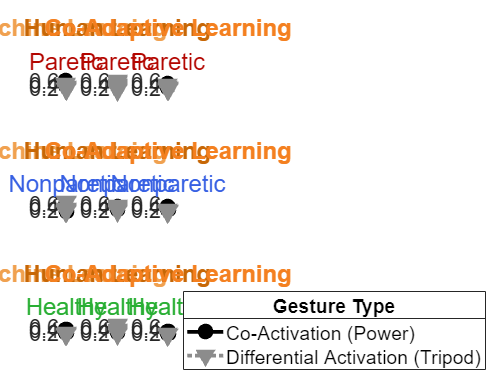

tlo = tiledlayout('flow');
fontsize(tlo, 20, "points")
% tlo.Units = 'inches';
% tlo.OuterPosition = [0 0 17 10.5];
ax_handle_list = [];
for cond = ["par", "xpar", "hlt"]
    y_cond = p_between(p_between.b_condition==cond,2:end);
    for task = ["Machine Learning", "Human Learning", "Co-Adaptive Learning"]
        y_coact = y_cond(:, and(p_within.w_task == task, p_within.w_gesture == "Co-Activation"));
        y_diffact = y_cond(:, and(p_within.w_task == task, p_within.w_gesture == "Differentiation"));
        ax_handle = nexttile;
        ax_handle_list = [ax_handle_list, ax_handle];
        hold on
        plot(y_coact{:,:}', '-ok', 'MarkerFaceColor','k', 'LineWidth',3,'MarkerSize',10 )
        plot(y_diffact{:,:}', ':v', 'MarkerFaceColor',"#8c8c8c", 'LineWidth',3,'MarkerSize',10, 'Color',"#8c8c8c")
        hold off
        title(task)
        switch task
            case "Machine Learning"
                title(task, 'Color', "#f0a150")
            case "Human Learning"
                title(task, 'Color', "#c76706")
            case "Co-Adaptive Learning"
                title(task, 'Color', "#f48020")
        end
        switch cond
            case "par"
                subtitle("Paretic", 'Color', "#b30600")
            case "xpar"
                subtitle("Nonparetic", 'Color', "#3760e3")
            case "hlt"
                subtitle("Healthy", 'Color', "#29af34")
        end
        xticks(1:9)
        yticks(0:0.2:0.8)
    end
end
legend_handle = legend(["Co-Activation (Power)",repmat("", 1, 4), "Differential Activation (Tripod)"], "Location","eastoutside");
title(legend_handle, "Gesture Type")
linkaxes(ax_handle_list, 'xy')
ylim([min(phi_between_arr,[], 'all'), max(phi_between_arr,[], 'all')])
xlim([0 5])
% title(tlo, sprintf("%s Vs. Trial Count", upper(metric_type)))
set(ax_handle_list, 'FontSize', 18)

[ctrlr_dict, ctrlr_keys, cond_keys] = table_to_dict(p_between, p_within);
[data_mean, data_sem, N] = compute_inf_stats(ctrlr_dict)

data_mean =     0.4025    0.3028    0.3650
    0.3212    0.3088    0.2309
    0.2430    0.2069    0.1757


data_sem =     0.0257    0.0167    0.0223
    0.0212    0.0268    0.0189
    0.0172    0.0135    0.0108


N = 40

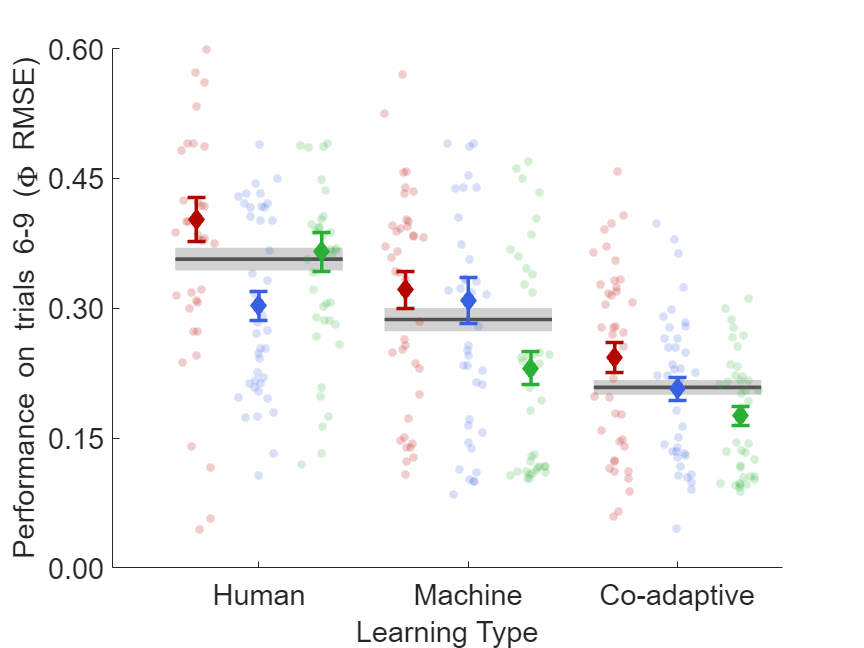

fig_h = figure;
set(fig_h, 'Renderer', 'painters');

fig_aspect = "PPT"; % IEEE-1, IEEE-2, PPT
if fig_aspect == "IEEE-1"
set(fig_h, "Units","centimeters", "Position", [15, 5, 8.89, 14.38])%IEEE
cap_size = 8; mk_size = 10;mk_size_err = 3;ln_width = 1.5;%IEEE
fig_fontsize = 8;
elseif fig_aspect == "PPT"
set(fig_h, "Units","inches", "Position", [6, 3, 10, 7.5])%PPT
cap_size = 15; mk_size = 50;mk_size_err = 10;ln_width = 3;%PPT
fig_fontsize = 24;
else
    error("Aspect (%s) not implemented", fig_aspect);
end

color_names = ["red", "blue", "green", "gray", "black"];
color_vals = {[179,6,0]/255, [55,96,227]/255, [41,175,52]/255, [153,153,153]/255, [26,26,26]/255};
color_scheme = dictionary(color_names, color_vals);
mk_alpha = 0.20;
xj_width = 0.5;
sem_factor = 1;

hold on
x_locs = [1.00,1.75,2.50,3.50,4.25,5.00,6.00,6.75,7.50];

patch_opts = {'FaceColor', color_scheme{"gray"}, 'EdgeColor', 'none', 'FaceAlpha', 0.45};
group_x_offset = 0.25;
group_x = [x_locs(1)-group_x_offset, x_locs(3)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"}; ctrlr_dict{"Human Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Human Learning"}{"paretic"};ctrlr_dict{"Human Learning"}{"nonparetic"}; ctrlr_dict{"Human Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
plot(group_x, group_mean, 'LineWidth', 3, 'Color', color_scheme{"black"})
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch(patch_x, patch_y, 1, patch_opts{:});

group_x = [x_locs(4)-group_x_offset, x_locs(6)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"}; ctrlr_dict{"Machine Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Machine Learning"}{"paretic"};ctrlr_dict{"Machine Learning"}{"nonparetic"}; ctrlr_dict{"Machine Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
plot(group_x, group_mean, 'LineWidth', 3, 'Color', color_scheme{"black"})
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch(patch_x, patch_y, 1, patch_opts{:});

group_x = [x_locs(7)-group_x_offset, x_locs(9)+group_x_offset];
group_mean = ones(size(group_x))*mean([ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}; ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}]);
group_sem = ones(size(group_x))*std([ctrlr_dict{"Co-Adaptive Learning"}{"paretic"};ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}; ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}])/sqrt(3*N)*sem_factor;
plot(group_x, group_mean, 'LineWidth', 3, 'Color', color_scheme{"black"})
patch_x = [group_x, fliplr(group_x)];
patch_y = [group_mean+group_sem, fliplr(group_mean-group_sem)];
patch(patch_x, patch_y, 1, patch_opts{:});

swarm_opts = {'filled', 'MarkerFaceAlpha', mk_alpha, 'XJitter', 'randn', 'XJitterWidth', xj_width};
swarmchart(x_locs(1)*ones(N,1), ctrlr_dict{"Human Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(2)*ones(N,1), ctrlr_dict{"Human Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(3)*ones(N,1), ctrlr_dict{"Human Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

swarmchart(x_locs(4)*ones(N,1), ctrlr_dict{"Machine Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(5)*ones(N,1), ctrlr_dict{"Machine Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(6)*ones(N,1), ctrlr_dict{"Machine Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

swarmchart(x_locs(7)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"paretic"}, mk_size, color_scheme{"red"}, swarm_opts{:})
swarmchart(x_locs(8)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"}, mk_size, color_scheme{"blue"}, swarm_opts{:})
swarmchart(x_locs(9)*ones(N,1), ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}, mk_size, color_scheme{"green"}, swarm_opts{:})

ebar_opts = {'LineStyle', 'none', 'LineWidth', ln_width, 'Marker', 'd', 'MarkerSize', mk_size_err, 'CapSize', cap_size};
plt_h(1) = errorbar(x_locs(1:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"paretic"}); mean(ctrlr_dict{"Machine Learning"}{"paretic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})], ...
           [std(ctrlr_dict{"Human Learning"}{"paretic"}); std(ctrlr_dict{"Machine Learning"}{"paretic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"paretic"})]/sqrt(N)*sem_factor, ...
           ebar_opts{:}, 'Color', color_scheme{"red"}, 'MarkerFaceColor', color_scheme{"red"});
plt_h(2) = errorbar(x_locs(2:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"nonparetic"}); mean(ctrlr_dict{"Machine Learning"}{"nonparetic"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})], ...
           [std(ctrlr_dict{"Human Learning"}{"nonparetic"}); std(ctrlr_dict{"Machine Learning"}{"nonparetic"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"})]/sqrt(N)*sem_factor, ...
           ebar_opts{:}, 'Color', color_scheme{"blue"}, 'MarkerFaceColor', color_scheme{"blue"});
plt_h(3) = errorbar(x_locs(3:3:9)', ...
           [mean(ctrlr_dict{"Human Learning"}{"healthy"}); mean(ctrlr_dict{"Machine Learning"}{"healthy"}); mean(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})], ...
           [std(ctrlr_dict{"Human Learning"}{"healthy"}); std(ctrlr_dict{"Machine Learning"}{"healthy"}); std(ctrlr_dict{"Co-Adaptive Learning"}{"healthy"})]/sqrt(N)*sem_factor, ...
           ebar_opts{:}, 'Color', color_scheme{"green"}, 'MarkerFaceColor', color_scheme{"green"});
hold off

% xlim([0,10])
xlabel("Learning Type")
xticks(x_locs(2:3:9))
xticklabels(["Human", "Machine", "Co-adaptive"])
ylabel("Performance on trials 6-9 (\Phi RMSE)")
yticks(0:0.15:0.75)
ytickformat('%0.2f')

if fig_aspect == "IEEE-1"
ylim([0.00, 0.75])%IEEE
legend(plt_h, "Paretic", "Non-Paretic", "Healthy") %IEEE
elseif fig_aspect == "PPT"
ylim([0.00, 0.60])%PPT
else
    error("Aspect (%s) not implemented", fig_aspect);
end
fontsize(fig_h, fig_fontsize,"points")%PPT

% title("Final Performance")

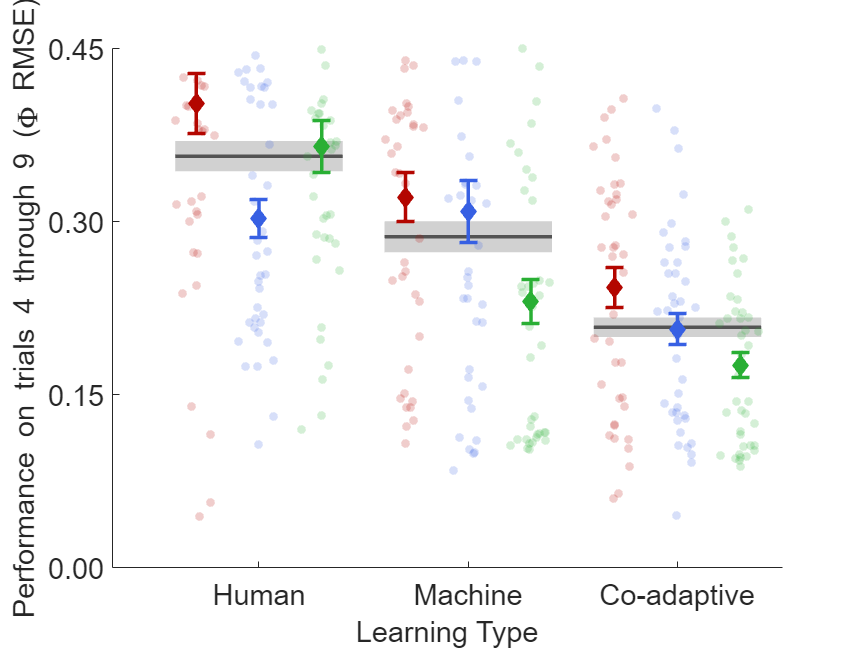

print(fig_h, '../../results/eps-figs/phi-rmse', '-depsc', '-r600', '-vector')

figure
raincloud_data = [
    [ctrlr_dict{"Human Learning"}{"paretic"},ctrlr_dict{"Human Learning"}{"nonparetic"},ctrlr_dict{"Human Learning"}{"healthy"}],...
    [ctrlr_dict{"Machine Learning"}{"paretic"},ctrlr_dict{"Machine Learning"}{"nonparetic"},ctrlr_dict{"Machine Learning"}{"healthy"}],...
    [ctrlr_dict{"Co-Adaptive Learning"}{"paretic"},ctrlr_dict{"Co-Adaptive Learning"}{"nonparetic"},ctrlr_dict{"Co-Adaptive Learning"}{"healthy"}]
]

raincloud_data =     0.2737    0.2707    0.3934    0.4572    0.3341    0.2441    0.2702    0.2548    0.2555
    0.4182    0.4162    0.4899    0.6703    0.4899    0.4043    0.3333    0.3238    0.2054
    0.4899    0.4440    0.3934    0.5706    0.3319    0.4696    0.3150    0.3794    0.2323
    0.3089    0.2420    0.4491    0.3328    0.4531    0.3850    0.3323    0.2646    0.2161
    0.4176    0.4206    0.3065    0.3826    0.3313    0.2357    0.2715    0.2830    0.3107
    0.2729    0.2530    0.4060    0.3942    0.3564    0.2263    0.3236    0.2166    0.2214
    0.3879    0.4292    0.4882    0.5252    0.4899    0.3677    0.3648    0.3985    0.2117
    0.4871    0.3315    0.3682    0.4352    0.2138    0.4343    0.4070    0.2789    0.2170
    0.3177    0.3173    0.2674    0.3924    0.4397    0.3454    0.1963    0.2352    0.2218
    0.3799    0.4175    0.2864    0.3998    0.3182    0.2467    0.4575    0.2308    0.2685


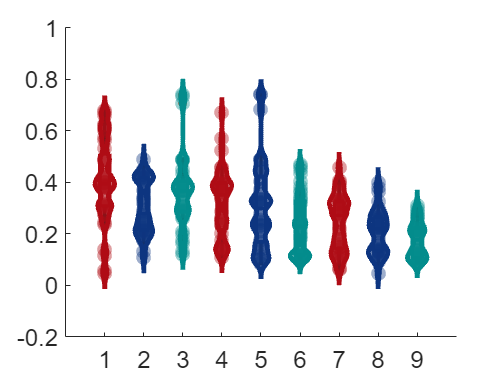

ans =   Figure (23) with properties:

      Number: 23
        Name: ''
       Color: [1 1 1]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


frm_dviz_utils.plot_rainclouds(raincloud_data, 'triple', 'vase', 0.02)

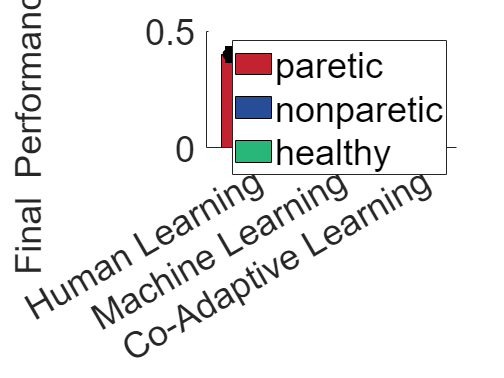

fig_h = plot_grouped_bars(data_mean, data_sem, ctrlr_keys, cond_keys);
ylabel(fig_h, "Final Performance (\Phi)")

### Export to R

r_dataframe = [];
for i=1:height(p_between)
    if or(p_between{i,1} == "par", p_between{i,1} == "xpar")
        p_id = i+mod(i,2);
    else
        p_id = i;
    end
    p_tbl = array2table([p_between{i,2:end}', repmat(sprintf("p%02d",p_id), height(p_within),1), repmat(p_between{i,1}, height(p_within),1), p_within{:,:}], ...
        "VariableNames", ["rmse", "p_id", "p_cond", "task_type", "gesture_type", "trial_num"]);
    r_dataframe = [r_dataframe; p_tbl];
end

r_dataframe = convertvars(r_dataframe, ["rmse"], 'double');
r_dataframe = convertvars(r_dataframe, ["trial_num"], 'double');
r_dataframe = convertvars(r_dataframe, ["gesture_type", "task_type", "p_cond", "p_id"], 'categorical');
r_dataframe = r_dataframe(:,{'rmse' 'trial_num' 'gesture_type' 'task_type' 'p_cond', 'p_id'})

r_dataframe = 360×6 table
      rmse      trial_num     gesture_type         task_type        p_cond    p_id
    ________    _________    _______________    ________________    ______    ____

     0.45718        1        Co-Activation      Machine Learning     par      p02 
     0.39423        2        Co-Activation      Machine Learning     par      p02 
     0.38462        3        Co-Activation      Machine Learning     par      p02 
     0.34256        4        Co-Activation      Machine Learning     par      p02 
     0.17235        1        Differentiation    Machine Learning     par      p02 
     0.23068        2        Differentiation    Machine Learning     par      p02 
     0.14713        3        Differentiation    Machine Learning     par      p02 
     0.28512        4 

writetable(r_dataframe, '../../temp-data/rdf_rmse_phi_10.csv','WriteMode','overwrite')

### 2-Way ANOVA

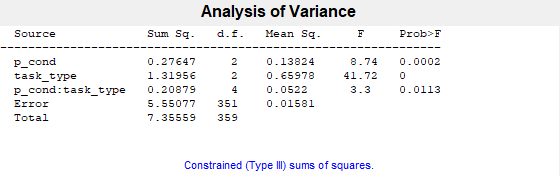

[pvals,anova_tbl,stats, terms] = anovan( r_dataframe{:,"rmse"}, ...
                                        {r_dataframe{:,"p_cond"}, r_dataframe{:,"task_type"}}, ...
                                        'varnames',["p_cond", "task_type"], ...
                                        'model',2);

pvals

pvals =     0.0002
    0.0000
    0.0113


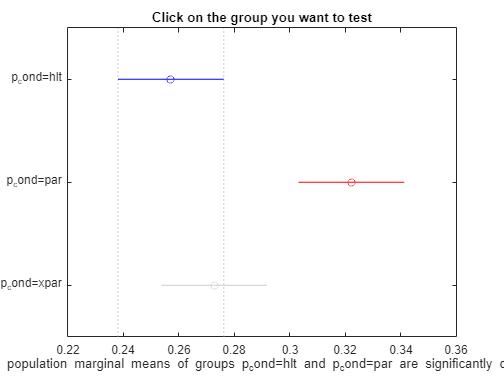

results =     1.0000    2.0000   -0.1031   -0.0650   -0.0270    0.0002
    1.0000    3.0000   -0.0537   -0.0156    0.0224    0.6009
    2.0000    3.0000    0.0114    0.0494    0.0875    0.0066


estimates =     0.2572    0.0115
    0.3222    0.0115
    0.2728    0.0115


group_names = 3×1 cell array
    {'p_cond=hlt' }
    {'p_cond=par' }
    {'p_cond=xpar'}


figure
[results, estimates, ~, group_names] = multcompare(stats, "Dimension",[1])

format short
tbl = array2table(results,"VariableNames", ...
    ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
tbl.("Group") = group_names(tbl.("Group"));
tbl.("Control Group") = group_names(tbl.("Control Group"))

tbl = 3×6 table
        Group          Control Group     Lower Limit    Difference    Upper Limit     P-value  
    ______________    _______________    ___________    __________    ___________    __________

    {'p_cond=hlt'}    {'p_cond=par' }      -0.10307     -0.065019      -0.02697      0.00018327
    {'p_cond=hlt'}    {'p_cond=xpar'}     -0.053668     -0.015619      0.022431         0.60092
    {'p_cond=par'}    {'p_cond=xpar'}      0.011351      0.049401       0.08745       0.0066253


estimates

estimates =     0.2572    0.0115
    0.3222    0.0115
    0.2728    0.0115


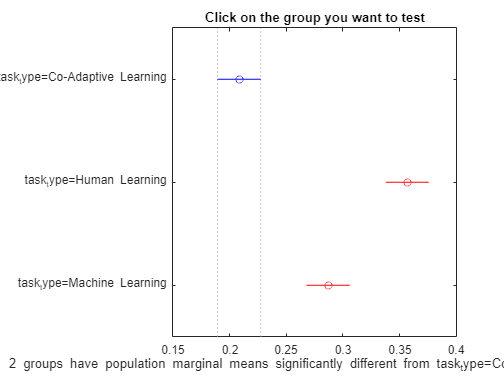

results =     1.0000    2.0000   -0.1863   -0.1482   -0.1102    0.0000
    1.0000    3.0000   -0.1164   -0.0784   -0.0403    0.0000
    2.0000    3.0000    0.0318    0.0698    0.1079    0.0001


estimates =     0.2085    0.0115
    0.3568    0.0115
    0.2869    0.0115


group_names = 3×1 cell array
    {'task_type=Co-Adaptive Learning'}
    {'task_type=Human Learning'      }
    {'task_type=Machine Learning'    }


[results, estimates, ~, group_names] = multcompare(stats, "Dimension",[2])

format short
tbl = array2table(results,"VariableNames", ...
    ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
tbl.("Group") = group_names(tbl.("Group"));
tbl.("Control Group") = group_names(tbl.("Control Group"))

tbl = 3×6 table
                  Group                           Control Group             Lower Limit    Difference    Upper Limit     P-value  
    __________________________________    ______________________________    ___________    __________    ___________    __________

    {'task_type=Co-Adaptive Learning'}    {'task_type=Human Learning'  }     -0.18627       -0.14822      -0.11017      5.9223e-20
    {'task_type=Co-Adaptive Learning'}    {'task_type=Machine Learning'}     -0.11645      -0.078399      -0.04035      4.0981e-06
    {'task_type=Human Learning'      }    {'task_type=Machine Learning'}     0.031768       0.069817       0.10787      5.0643e-05


estimates

estimates =     0.2085    0.0115
    0.3568    0.0115
    0.2869    0.0115


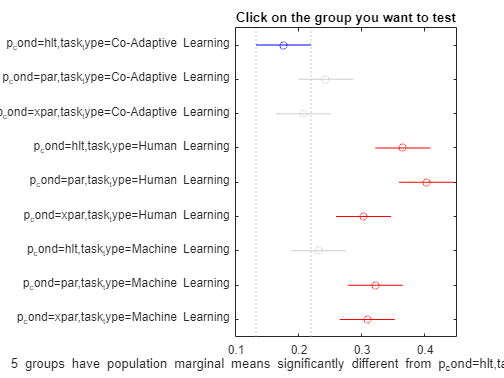

results =     1.0000    2.0000   -0.1545   -0.0672    0.0200    0.2887
    1.0000    3.0000   -0.1184   -0.0312    0.0560    0.9731
    1.0000    4.0000   -0.2765   -0.1893   -0.1021    0.0000
    1.0000    5.0000   -0.3140   -0.2267   -0.1395    0.0000
    1.0000    6.0000   -0.2143   -0.1270   -0.0398    0.0002
    1.0000    7.0000   -0.1423   -0.0551    0.0321    0.5713
    1.0000    8.0000   -0.2327   -0.1455   -0.0583    0.0000
    1.0000    9.0000   -0.2202   -0.1330   -0.0458    0.0001
    2.0000    3.0000   -0.0512    0.0361    0.1233    0.9368
    2.0000    4.0000   -0.2093   -0.1220   -0.0348    0.0005


estimates =     0.1757    0.0199
    0.2430    0.0199
    0.2069    0.0199
    0.3650    0.0199
    0.4025    0.0199
    0.3028    0.0199
    0.2309    0.0199
    0.3212    0.0199
    0.3088    0.0199


group_names = 9×1 cell array
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }
    {'p_cond=par,task_type=Co-Adaptive Learning' }
    {'p_cond=xpar,task_type=Co-Adaptive Learning'}
    {'p_cond=hlt,task_type=Human Learning'       }
    {'p_cond=par,task_type=Human Learning'       }
    {'p_cond=xpar,task_type=Human Learning'      }
    {'p_cond=hlt,task_type=Machine Learning'     }
    {'p_cond=par,task_type=Machine Learning'     }
    {'p_cond=xpar,task_type=Machine Learning'    }


figure
[results, estimates, ~, group_names] = multcompare(stats, "Dimension",[1,2])

format short
tbl = array2table(results,"VariableNames", ...
    ["Group","Control Group","Lower Limit","Difference","Upper Limit","P-value"]);
tbl.("Group") = group_names(tbl.("Group"));
tbl.("Control Group") = group_names(tbl.("Control Group"))

tbl = 36×6 table
                        Group                                         Control Group                     Lower Limit    Difference    Upper Limit     P-value  
    ______________________________________________    ______________________________________________    ___________    __________    ___________    __________

    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=par,task_type=Co-Adaptive Learning' }      -0.15446     -0.067237       0.019983        0.28865
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=xpar,task_type=Co-Adaptive Learning'}       -0.1184     -0.031184       0.056035        0.97309
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=hlt,task_type=Human Learning'       }      -0.27649      -0.18927       -0.1020

tbl(:, ["Group", "Control Group", "P-value"])

ans = 36×3 table
                        Group                                         Control Group                      P-value  
    ______________________________________________    ______________________________________________    __________

    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=par,task_type=Co-Adaptive Learning' }       0.28865
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=xpar,task_type=Co-Adaptive Learning'}       0.97309
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=hlt,task_type=Human Learning'       }    5.1482e-10
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=par,task_type=Human Learning'       }    1.0455e-14
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=xpar,task_type=Human Learning'      }    0.00021493
    {'p_cond=hlt,task_type=Co-Adaptive Learning' }    {'p_cond=hlt,task_typ

estimates

estimates =     0.1757    0.0199
    0.2430    0.0199
    0.2069    0.0199
    0.3650    0.0199
    0.4025    0.0199
    0.3028    0.0199
    0.2309    0.0199
    0.3212    0.0199
    0.3088    0.0199
